%%RUN THIS TO EXECUTE Modified-HOA
[VarMin, VarMax, nVar] = HOA_Final_InitialData;
z = @HOA_Final_Functions;

%Number of runs to find average performance, standard deviation, etc.
NRuns = 10;
%Population Size
nHorse = 50;
%Total Number of iterations in each run
MaxIt = 1000;

empty_GlobalBestHOA.Position=[];
empty_GlobalBestHOA.Cost=[];
GlobalBestHOA=repmat(empty_GlobalBestHOA,NRuns,1);

BestCostHOA = zeros(NRuns, MaxIt);

for i = 1:NRuns
   [BestCostHOA(i,:), GlobalBestHOA(i)] = HOA(z,nVar,VarMin, VarMax, nHorse, MaxIt);
%    disp([ ' m-HOA: Best Position = '  num2str(GlobalBestHOA(i).Position)])
%    disp([ ' m-HOA: Best Cost = '  num2str(GlobalBestHOA(i).Cost)])
%    disp([ ' Time = '  num2str(toc)])
end

 m-HOA: Best Position = 1.8133      1.0893     -1.9882       1.873     -3.3055     -2.6367      2.4032     -3.0426      2.7739     -1.2772      1.5155     -1.8183     -2.9725    -0.82641     -2.5701      2.1424      1.2396      2.9814     -1.5046      2.9296      2.4105    -0.62515     0.99669     -1.7943    -0.68367     -1.5529      -1.545     -2.2494     -3.1824     -1.6341      -2.165       1.299     -2.1884     -2.0243     -2.7678      1.8026      2.0722     -2.1179     -3.3672      1.8805       3.151    -0.15728     -2.4218      1.6868      2.7733      -1.719     -1.5359     -1.5458     -2.3035      -2.092      2.6937     -3.9633      2.8399     -2.4705     -2.8499     0.89655      2.1664     -2.2322     -3.1169      1.6285      2.2567      1.7673    -0.10248      2.5323     -1.2272     -1.8074        2.66     -2.0345      -2.221      2.5352      1.6381     -2.3886    -0.78653     -2.9347       1.814    -0.76759      1.6389     -1.8145      2.0293     -2.0519      -2.516     -2.75

 m-HOA: Best Cost = -2241.2914


 Time = 3.4737


 m-HOA: Best Position = -3.1597     -2.6372      2.1171      2.2718     -2.5979     -1.6216      1.6601     -3.3368     -2.5583      3.2222      2.4453      -2.592      1.5504      3.4581       -2.34     -2.9104      -2.595      2.9712     0.86685     -2.5053     -1.7845     -2.4335     -1.7169        2.11     -2.6972      3.3367      1.7766      1.3885     -2.4116     -1.1448      1.2202      2.2242     -1.5212     -2.8043      1.4487       1.742      2.9557     -2.5318      3.0081      1.3144     0.23731      2.8767      2.3763     -2.3108      2.8387     -2.8344     -2.2156      1.8301   -0.050597     -2.0084      1.6698      -1.931       2.358     -1.3246      1.1145      2.7639      2.1477      1.4696      3.0205      1.1652   0.0032754     0.64163     -1.3599      1.2778     -3.3686     -2.9297      2.2288     -1.1193      1.2859     -2.2295      1.8409     -2.1594     0.38528     -1.8651     -1.7316     -2.6243      1.5584    -0.55956     -2.8367      1.9749     -2.3539      2.6

 m-HOA: Best Cost = -2294.9306


 Time = 3.4708


 m-HOA: Best Position = -1.2089     -2.1504     -2.1908       1.864     -1.7707       2.126    -0.95918      2.3102      2.5375    -0.13545      1.9529     -2.7622    -0.11341     -2.6018      3.0408     -1.0006     -1.4164     -2.7016     -2.5923     -1.8492      2.2511     -2.7715       2.473      3.1503      1.4482     -2.1095     -2.4153    -0.31008    -0.29036      2.0523      -2.412      2.5821     -0.6811     -1.8185      2.4362     -1.3592     -3.2233      2.1909    -0.42953     -3.1672       -2.33      1.9261      2.2492    -0.83328     0.39816     -2.1167     0.63457     0.71521       2.013      2.5028     -1.2948     -3.2737      3.1515       3.105      1.9185      -2.878     -1.5369     -2.1745     0.86149      1.1687      1.2355     -1.0491    -0.32588       2.567      2.3967     -1.0352      1.0438     -1.2439        -3.1     -2.0629       1.211      -2.801     -2.7917     -2.6744      1.5354     -1.9848    -0.13113     -2.1359    -0.44327     -1.6107      2.3185     -1.9

 m-HOA: Best Cost = -2051.464


 Time = 3.2956


 m-HOA: Best Position = 2.4379      2.7702   -0.057079      1.9572      2.9483    0.040941      2.1563      2.4058      1.3457     -3.3204      2.0836     -2.0905     -1.9879      2.0893      2.4224     -1.1204      4.1884     -1.8426     0.69574      2.8486      1.9079    -0.14068     0.29237     -1.0153    -0.93214      1.1982      2.1639     -1.6388      -2.346     -2.9408     -1.6818     -3.4329     -2.2328     -1.1944      1.9288     -2.2858    0.041072      2.8227    -0.92736     0.62842      2.7129     -2.7653     -2.3032     -1.5445      1.2824 -0.00045151     -2.4896      2.0078    -0.66768     -3.4675       2.523      -2.069      -3.357     -2.8397      1.6593     -1.4009      1.6904      2.0125     -1.0919    -0.39292     -2.9182      2.6025     -1.1995      2.3242      2.1406      1.7586      1.6727       2.592       1.826     -2.1116     -2.2012       -2.43      3.2588     0.74597     -2.1267     -3.4156     -3.1022      3.5502     -2.3481     -1.0533     -3.0086     -1.53

 m-HOA: Best Cost = -2033.0846


 Time = 3.4039


 m-HOA: Best Position = -3.4829      1.7009     -1.2854     -2.8501      2.2097      1.3036     -3.2939      2.3621      2.1155     -0.2274      1.4123     -2.4514      1.3873    -0.49484     -2.5974      2.0468     -2.6813       1.034     -1.6383    -0.53757      2.4767     -2.4223      1.6955     -2.3123     -2.8461     -1.0257      1.3368      1.0645      3.0676     0.55343     -1.8808     -2.8404      2.6496      1.8291     -1.2855     -2.1338      1.5474        2.48      2.1649     -3.0808      -3.086      1.7664    -0.11347      2.8051      2.3511     -1.5463      1.9244     -1.6121     -2.1095     0.86639     -2.2044     -2.3006     0.39051    -0.21518    -0.31266    -0.69877    -0.58535      1.9965     0.33478        -2.5     -1.6173     -3.7241     0.38121      1.5061     0.64386     -1.4546     -1.1252      2.2441       2.706     -1.3467     -1.6998      1.9574     -3.4281      2.2374    -0.44464       2.728     -1.7371     0.64254      1.8378      -1.677      -1.966     -1.8

 m-HOA: Best Cost = -1947.5301


 Time = 3.4002


 m-HOA: Best Position = 0.44026     0.70872    -0.88664     -2.4096     -2.5566      2.4757     -1.9157     -3.3471     -1.8088      1.3328     -2.4512       1.724     -2.4693     0.90097     -1.7209     0.27774     -2.6153     -2.8448      1.9831     -0.5689      2.6248      1.7076      2.3438      1.4012    -0.53651     -2.1448      -1.806     -1.3759      -1.226      2.1277     -2.4175      1.9216      2.2851      1.5729     -1.0213     -3.5689     -2.8832     -2.9777    -0.58372      3.1578      2.1918      1.0061     -2.5294      1.3891      2.2596     -1.2534     -2.8657      -2.131      2.2675     -1.5618       2.612      -3.048      1.7061     -2.7963      2.6709      1.6943      -1.601   -0.025817     -2.9763      1.8738      3.1707      2.1682     -2.6691    -0.96538     -2.8506     -1.8015      2.1782     -3.0932     0.54291    -0.50184    -0.49672     -1.4036     -3.0702      1.9831     -1.6635     -1.3744     0.32664     0.33251      2.3229     0.51085      -3.036      1.5

 m-HOA: Best Cost = -2054.9259


 Time = 3.425


 m-HOA: Best Position = -1.6532       -1.83     -1.7453      1.3199     -3.0359     -1.2286     0.20846      2.6257     -2.1451     -2.3867     -1.4877    -0.95559       2.764    -0.84702      1.5055     -3.2078     -2.7857     -1.8847     -2.6707      1.5893      1.7203     -2.5006      3.0655      2.4767      3.2617     -1.6988     -2.5247      2.5628    -0.50984     -2.6522     -2.0483     -1.3414     -3.1021    0.079166     -2.7228     0.46313     -1.6095      1.2925      2.9831     -2.6693     -1.2932     -3.3795      2.4196     -2.0949      2.0909     -2.1251     -2.0812     -3.1923     -2.3071      -1.723     0.40727      2.4701     -2.1705     -2.4955       0.306       1.619      0.5891      2.0474     -2.7295     0.53923     -1.2225     -2.7216     -2.0599     0.73819     -2.2237       2.302     -1.8987       2.895      2.9065      2.2912      -2.967      2.8386       2.072      1.9746     -1.4904      1.6446     -2.1983     -2.4584      -1.483      1.3199     -2.8378    -0.31

 m-HOA: Best Cost = -2230.3232


 Time = 3.5738


 m-HOA: Best Position = -0.49784     -2.2627     -2.4504     -2.8244    -0.95628      1.5317     -1.3486     -2.9283     -2.5477      1.3616     -2.4383      2.9245    -0.27965     -3.0065      1.5467     -1.2257      2.3398     -1.8934      2.0336     -2.3507    -0.89931      1.9036     0.90409       2.105     -2.7853     -1.2706     -2.4897     -2.8958      2.6385      2.3988     -2.6557      1.0172     -2.6971       2.567       0.424      1.2729      2.1295      1.4682     -2.9579    -0.96116      1.7696    -0.61769      1.9976     -1.9513      2.6454     -0.9091     -1.1086     -2.6117     -3.1719     -2.9271     0.55897     -2.0113     0.26565     -2.5234     0.64728     -2.5813      -2.977     0.83948      2.6942     -1.0584     -2.7529      1.6554     -2.1739     -2.2003       1.003      1.6631     -3.1871     0.66096     -2.3477      1.9313     -1.4186     -1.5226     -2.9338    0.013691     -1.6829      1.4649      1.8292      2.5919      1.6806      2.3012    -0.10222      1.

 m-HOA: Best Cost = -2087.1366


 Time = 3.376


 m-HOA: Best Position = 1.4927      2.4292     -1.8288     0.10023     -1.9724     -2.2319     -2.2067     -0.6489     -3.4106      -1.711      1.8946     -2.9776       3.238    0.078703      1.8946     -1.8488      2.0098     -3.1251     -1.9418      -1.948     -2.7859     -3.2025      2.8488     0.53925      2.5855      2.7364      2.1361    -0.41691     -1.7668      1.8538     0.23741      2.2215      -1.741      1.7525     -1.6246     -1.4935     0.20399     -1.2024     0.42761     0.62401      3.0231      2.5374     -1.6363    -0.32828     -3.0789     -2.8448     -2.0724      2.1938     -2.1065     0.36414      2.3504      2.5943     -0.1235       1.158     -1.2406      1.9789      -1.846     -3.0544     -2.8244      2.0789     -3.5061      3.1823     -2.2564      1.0362      -2.844      2.2601     -2.3171     -1.3697     -2.4316      2.4196     0.37777    -0.77723      2.3596     0.85015     -2.5901     -3.3477     -2.7119      3.8607     -3.4841      1.9188    -0.51141     -2.50

 m-HOA: Best Cost = -2093.295


 Time = 3.576


 m-HOA: Best Position = 2.6002     -1.4672     0.71861     -2.7812      2.5846     -2.1475     -3.0847     -2.0063   -0.073851      -1.942      2.0828     -1.9974     -1.0405      -2.974      1.6834      2.1905      2.8801      -1.149    -0.31403      2.3509     -2.5947      -2.391      1.1796     -1.2036      1.7855     -2.5575      -2.243     -1.5936     -1.9931     -2.5951     -2.4324     -1.4144     0.61165      1.9166     -2.3263      2.6982      1.9643      2.3517       1.964      1.7208      2.1093     -2.6055     -1.3823      2.3348     -1.8968     -3.0588      2.1466      2.2895      3.0633     -2.1004     -2.1394      2.4929      2.0819      1.9166      2.8341      2.2908     0.99954     -1.2512      2.1351     -2.1889     -2.6885     -2.4285       2.538      2.1693      1.6044     -3.3673     -2.3562        2.13      2.3266      2.3533     -1.7206     -2.1266    -0.93359      2.8444      1.9418     -1.6229     0.46066      1.4752       1.237     -4.1164      1.9542      0.66

 m-HOA: Best Cost = -2245.8112


 Time = 3.4491


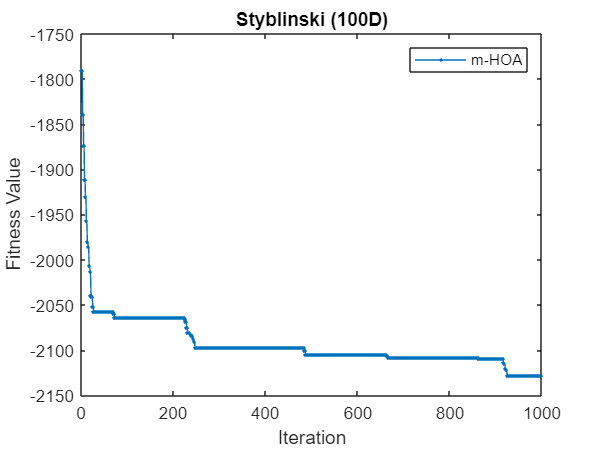


HOAIterData = mean(BestCostHOA, 1);

x = [1 : 1: 1000];
y = HOAIterData;
plot(x, y,'.-'), legend('m-HOA')
xlabel('Iteration');
ylabel('Fitness Value');
title('Styblinski (100D)');


% T = struct2table(GlobalBestHOA)
% filename = 'Modified_HOA Styblinski 100 Var.xlsx';
% writetable(T,filename);
